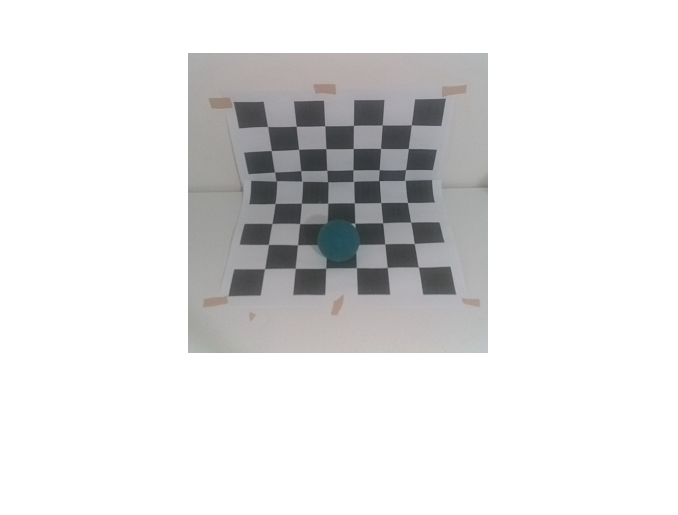

imshow(image_0)

P = [
   -0.0043    0.0013    0.0014   -0.3812
    0.0001    0.0042   -0.0017   -0.9244
    0.0000    0.0000    0.0000   -0.0063]

P =    -0.0043    0.0013    0.0014   -0.3812
    0.0001    0.0042   -0.0017   -0.9244
         0         0         0   -0.0063



pplus = P'*inv(P*P')

pplus = 	1.0e+04 *

   -0.0198    0.0030    0.7512
    0.0035    0.0200   -3.1449
    0.0074   -0.0092    0.9055
         0         0   -0.0159


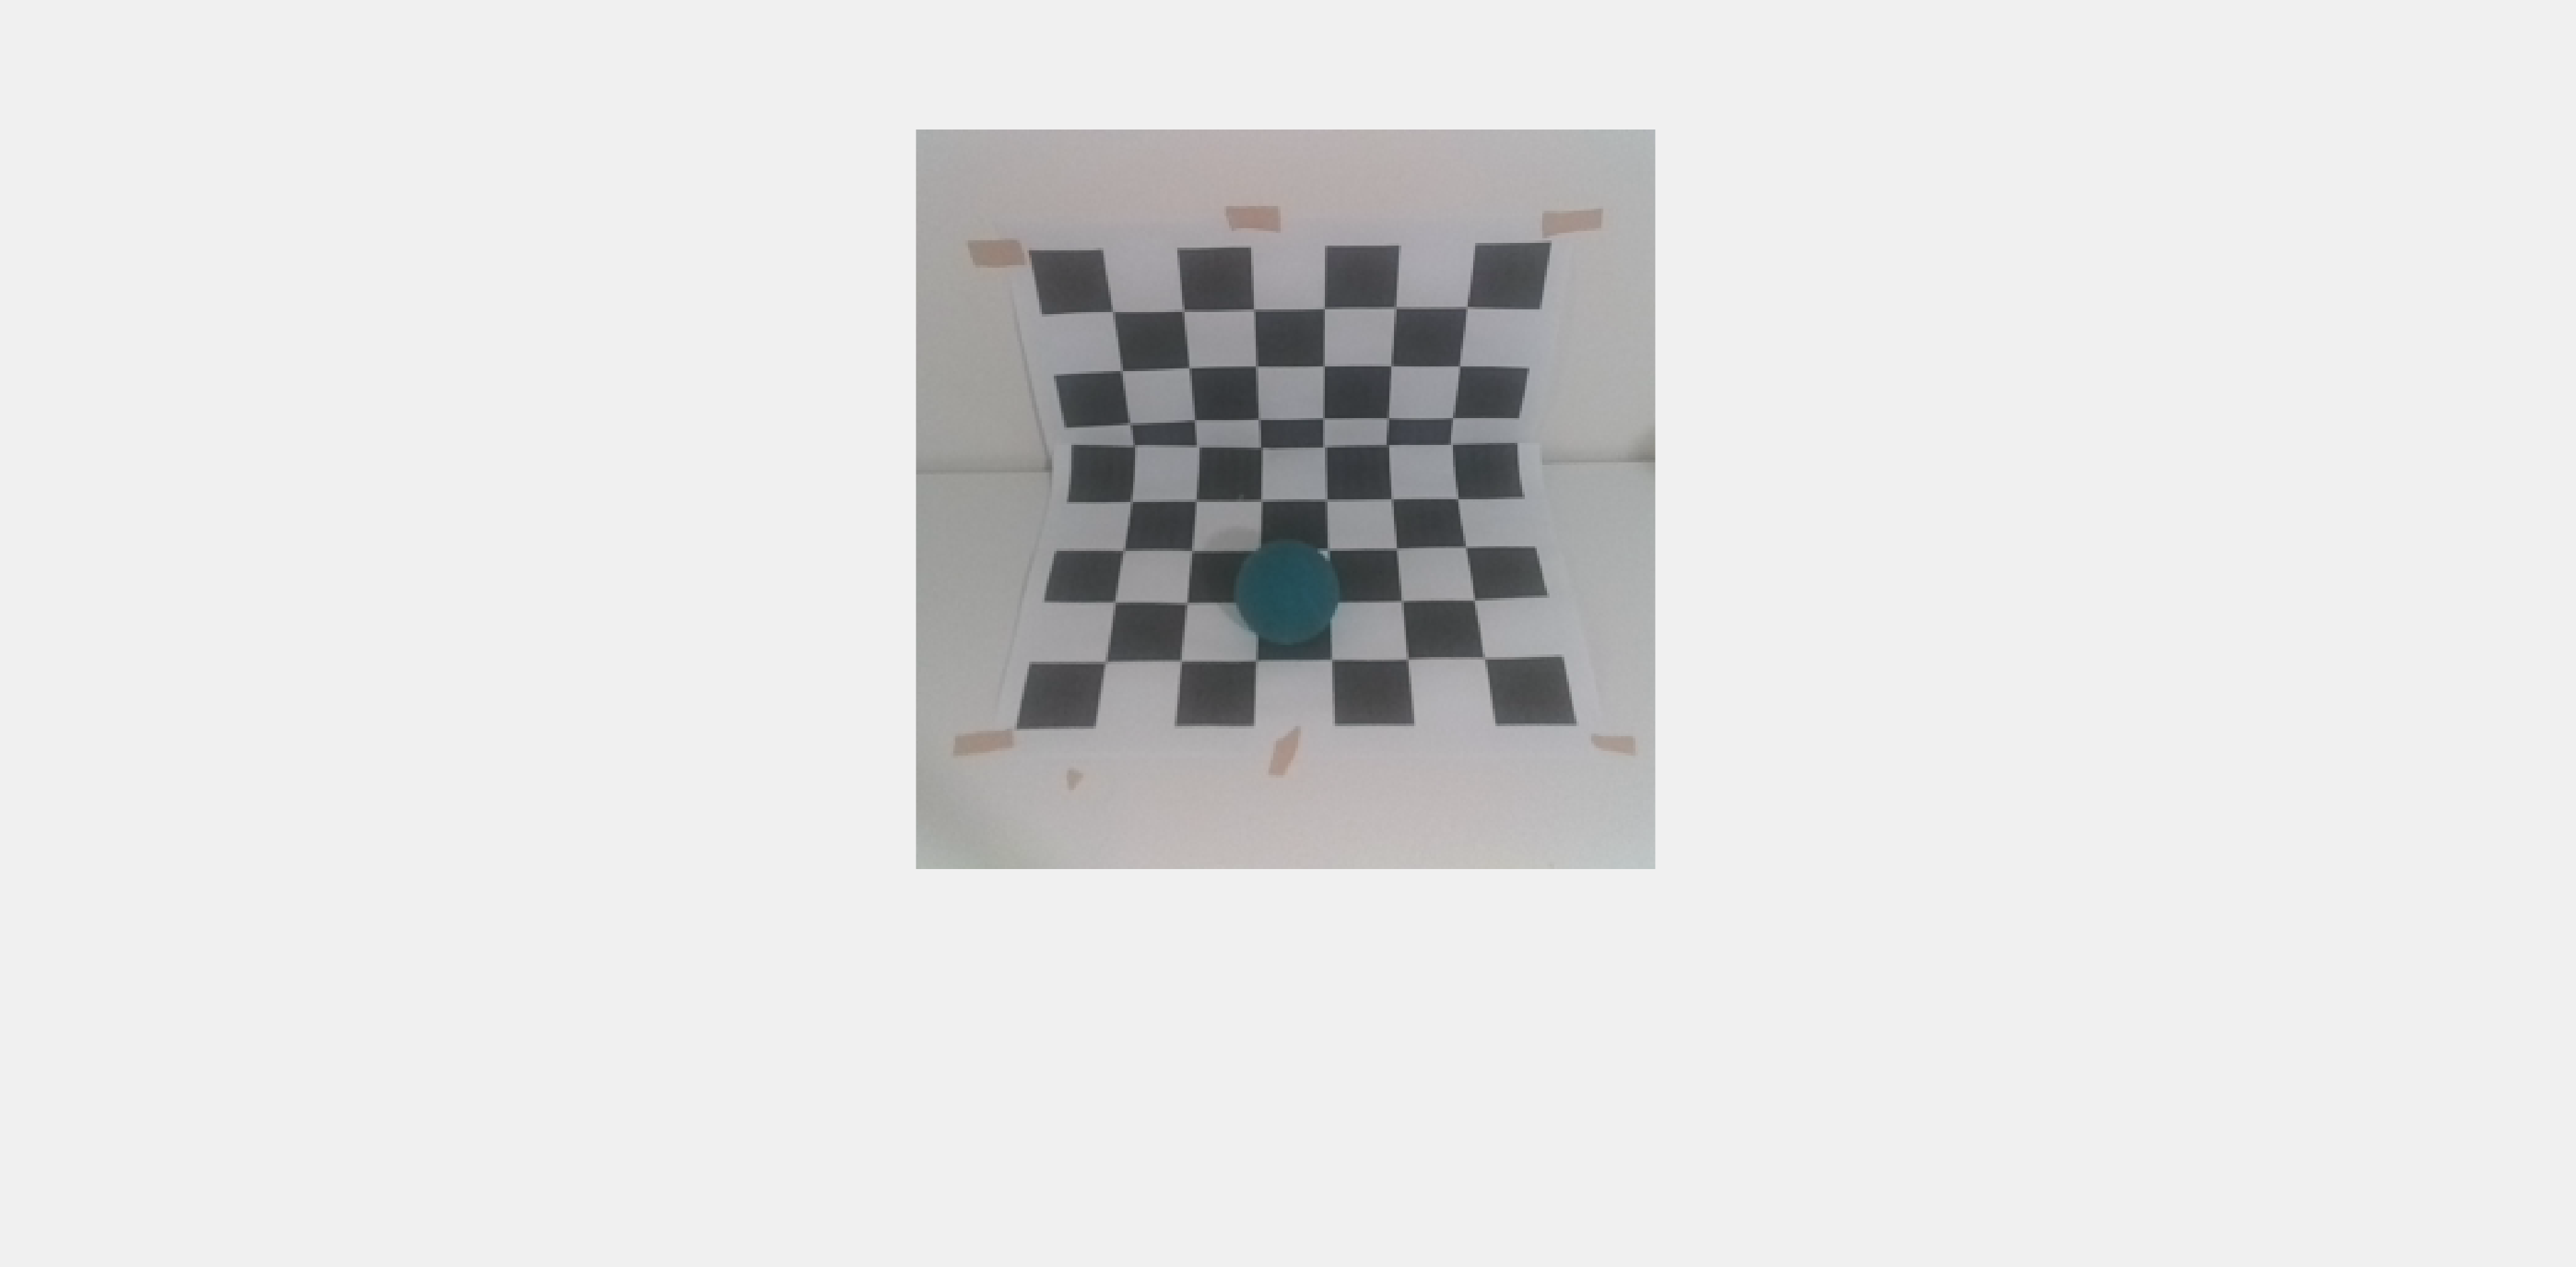

uv =   129.5381  189.0209
  172.5508  188.2042


uv = ginput(2)

uv = [uv ones(2,1)]

uv =   129.5381  189.0209    1.0000
  172.5508  188.2042    1.0000


a = pplus*uv(1,1:end)'

a = 	1.0e+04 *

   -1.2373
    1.0859
    0.1223
   -0.0159


a = a/a(end)

a =    77.9477
  -68.4095
   -7.7021
    1.0000


a = a(1:end-1)

a =    77.9477
  -68.4095
   -7.7021


b = pplus*uv(2,1:end)'

b = 	1.0e+04 *

   -2.0908
    1.2191
    0.4493
   -0.0159


b = b/b(end)    

b =   131.7193
  -76.8051
  -28.3077
    1.0000


b = b(1:end-1)

b =   131.7193
  -76.8051
  -28.3077


sqrt(sum(power(a-b,2)))

ans = 58.1933